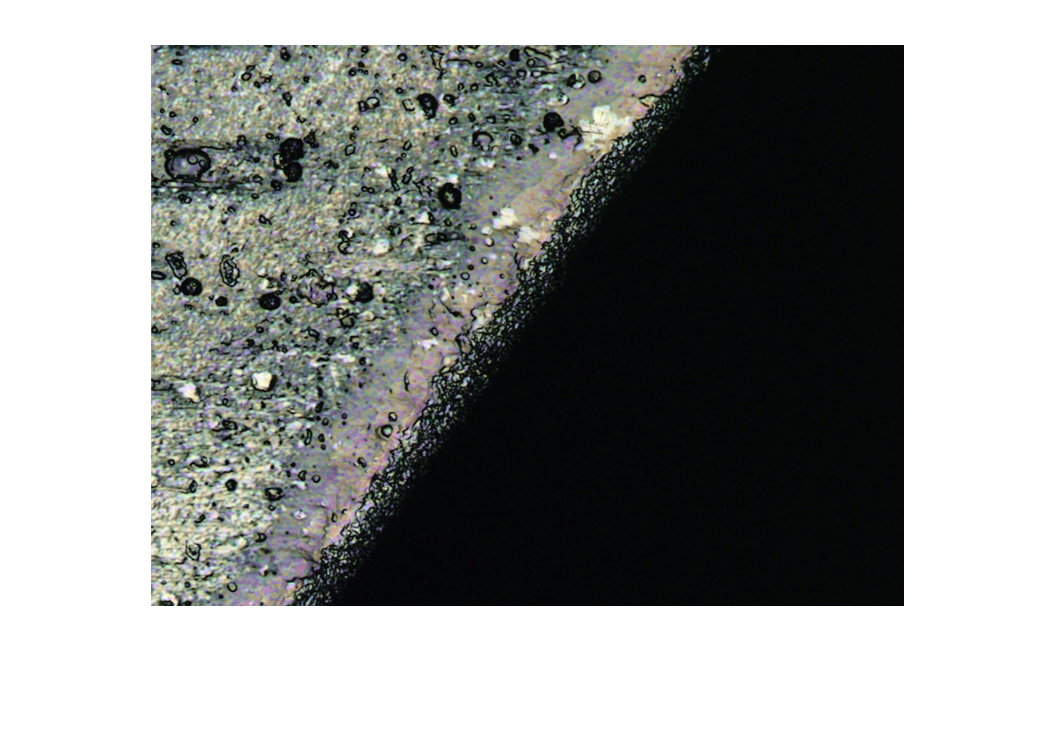

clc; clear; close all;
% Display original image
img=imread('50.bmp');
figure;imshow(img);%title('Original image');

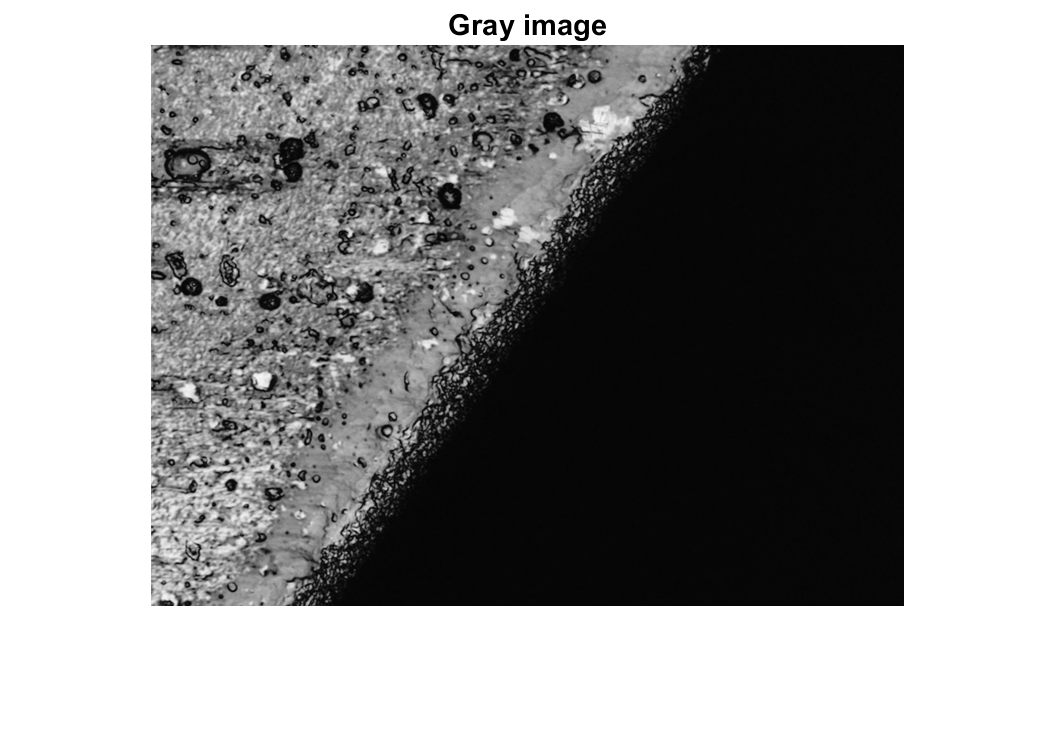

[rows,cols,colors]=size(img);
grayImg=zeros(rows,cols);
grayImg=uint8(grayImg);
for i=1:rows
    for j=1:cols
        sum1=0;
        for k=1:colors
            sum1=sum1+img(i,j,k)/3;
        end
        grayImg(i,j)=sum1;
    end
end
figure;imshow(grayImg);title('Gray image');

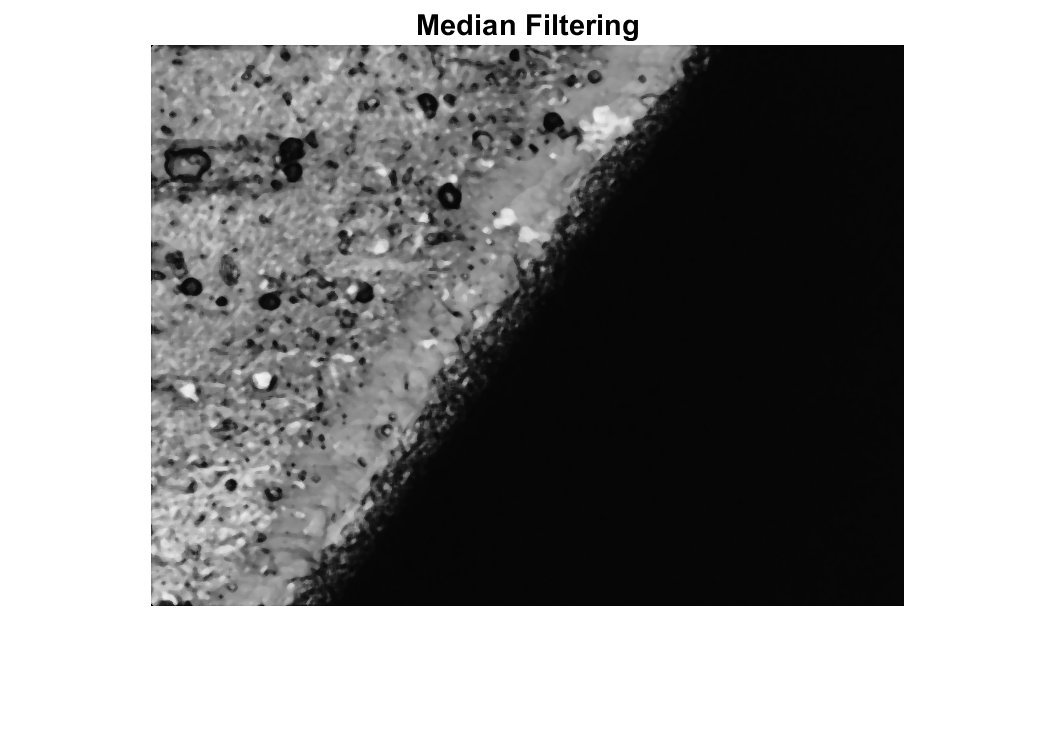

%图片滤波
GF1 = medfilt2(grayImg, [5, 5]);       %进行5*5模板中值滤波
figure;imshow(GF1);title('Median Filtering');

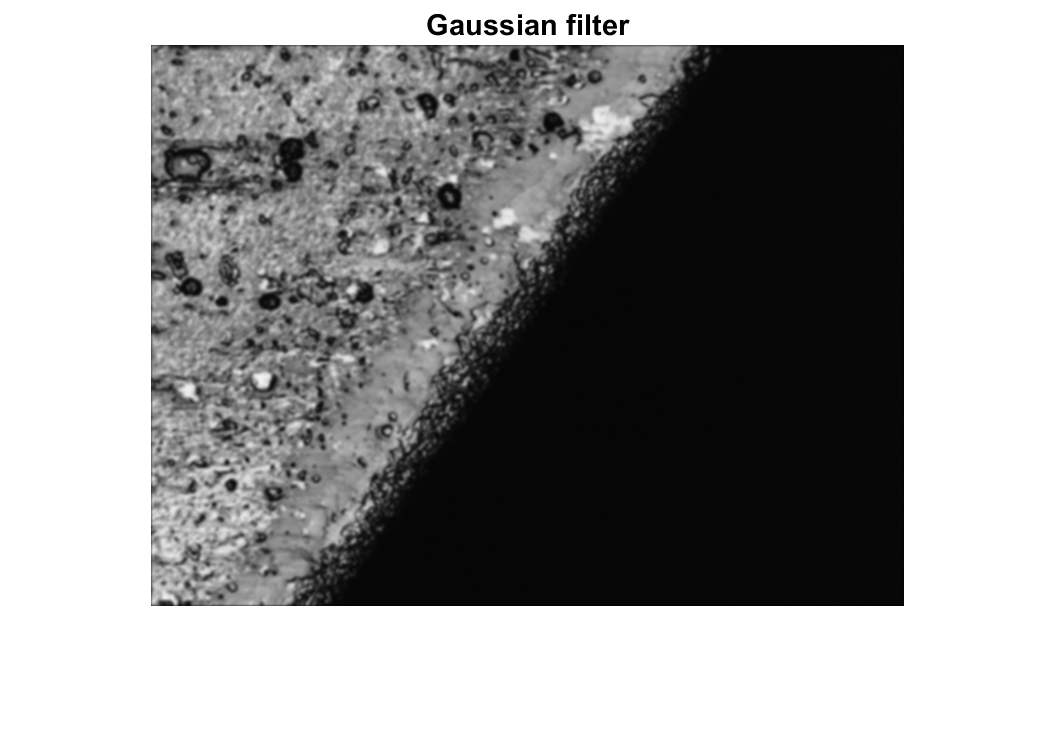

sigma = 1.5;      %sigma赋值
N = 2;            %大小是（2N+1）×（2N+1）
N_row = 2*N + 1;
gausFilter = fspecial('gaussian',[N_row N_row],sigma);      %matlab 自带高斯模板滤波
GF2=imfilter(grayImg, gausFilter, 'conv');
figure;imshow(GF2);title('Gaussian filter');

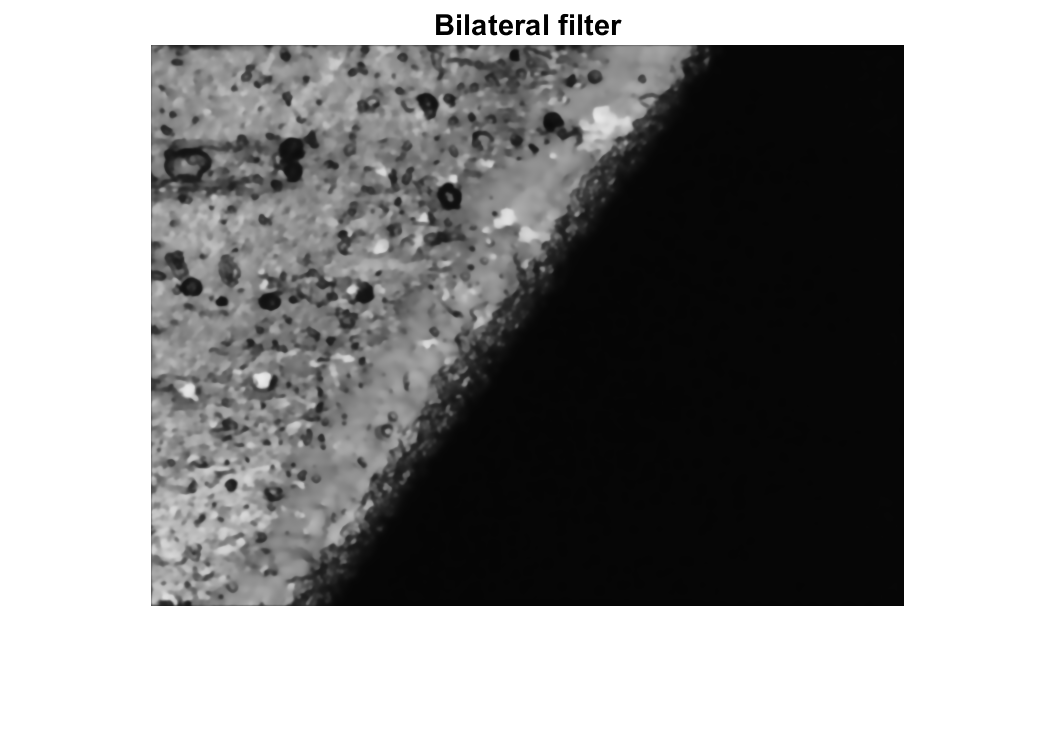

I=double(GF2)/255;  %转为double型并归一化
w= 5;              % 双边滤波器半宽，w越大平滑作用越强
sigma = [3 0.1];   % 空间距离方差σd记为SIGMA(1),像素亮度方差σr记为SIGMA(2),即空间邻近度因子和亮度相似度因子的衰减程度
GF3=bfilter2(I,w,sigma);                     %双边滤波器滤波
figure,imshow(GF3),title('Bilateral filter')%作出双边滤波后的图像

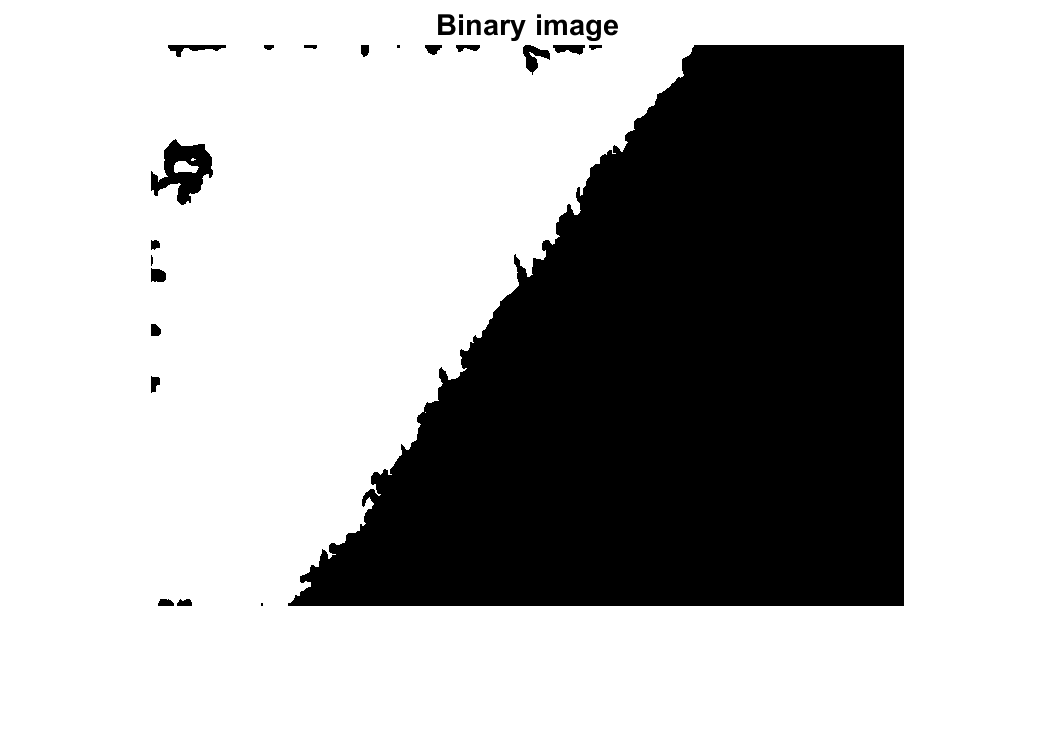

%%%%%%%%Binarization processing%%%%%%%%%%%%
[ori_row, ori_col] = size(GF3);
level=graythresh(GF3);
binaryImg=im2bw(GF3, level);   %#ok<IM2BW> %将灰度图像转化为二值图像，%%是否可以使用新方法，
% Get rid of small specks of noise
binaryImg = bwareaopen(binaryImg, 100);
binaryImg = imfill(binaryImg, 'holes');
se = [1;1;1]; %strel('diamond', 2)
binaryImg = imerode(binaryImg, se);
binaryImg = imerode(binaryImg,se);
figure;imshow(binaryImg);title('Binary image');

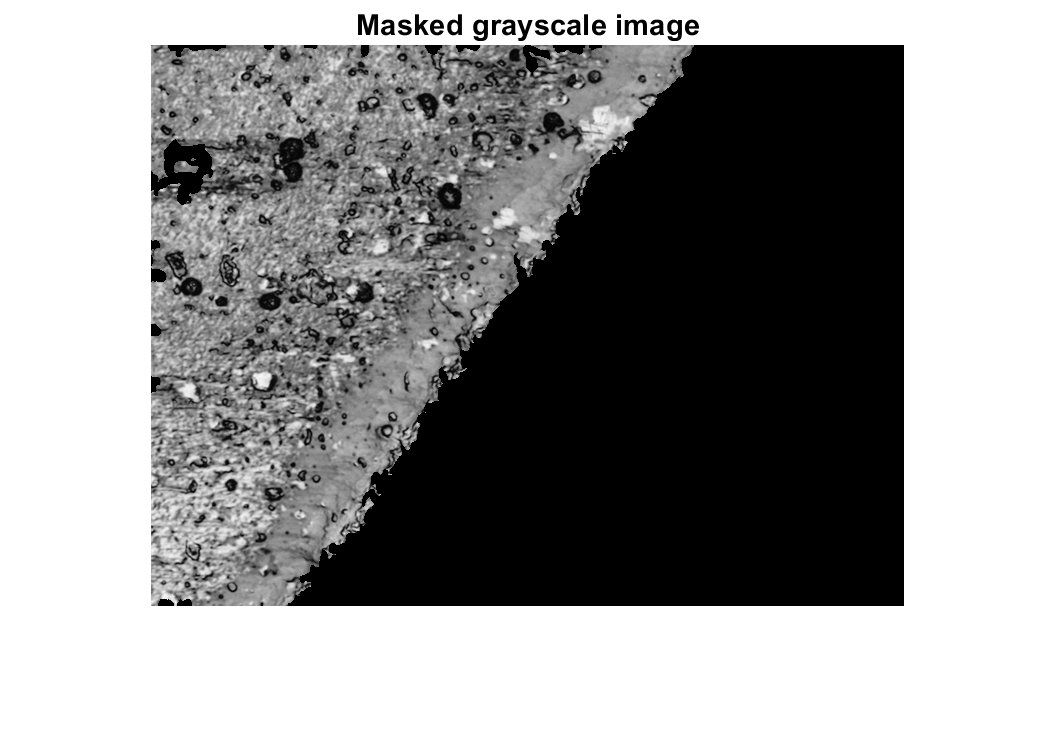

% Mask the gray image
finalImage = grayImg; % Initialize.
finalImage(~binaryImg) = 0;
finalImage = im2double(finalImage);
figure;imshow(finalImage);title('Masked grayscale image');

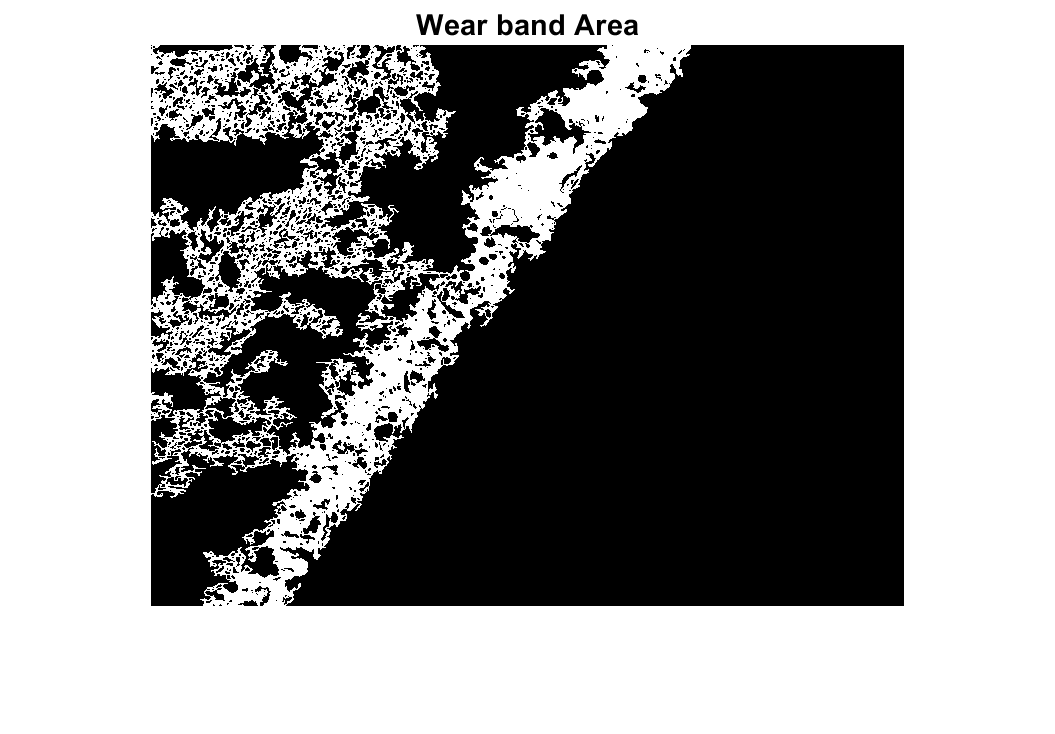

% finalImage = imadjust(finalImage);
J_1 = regiongrowing(finalImage, 0.096);
finalBinImage = J_1;
for item =1:7
    J_1 = regiongrowing(finalImage, 0.096);
    finalBinImage = finalBinImage+J_1;
end
figure;imshow(finalBinImage);title('Wear band Area');
%%%%%%%The area of interest%%%%%%%%%
offset = 110;
[y,~] = getpts;

x=[round(y(1)) round(y(2))];
y=[0 ori_row];

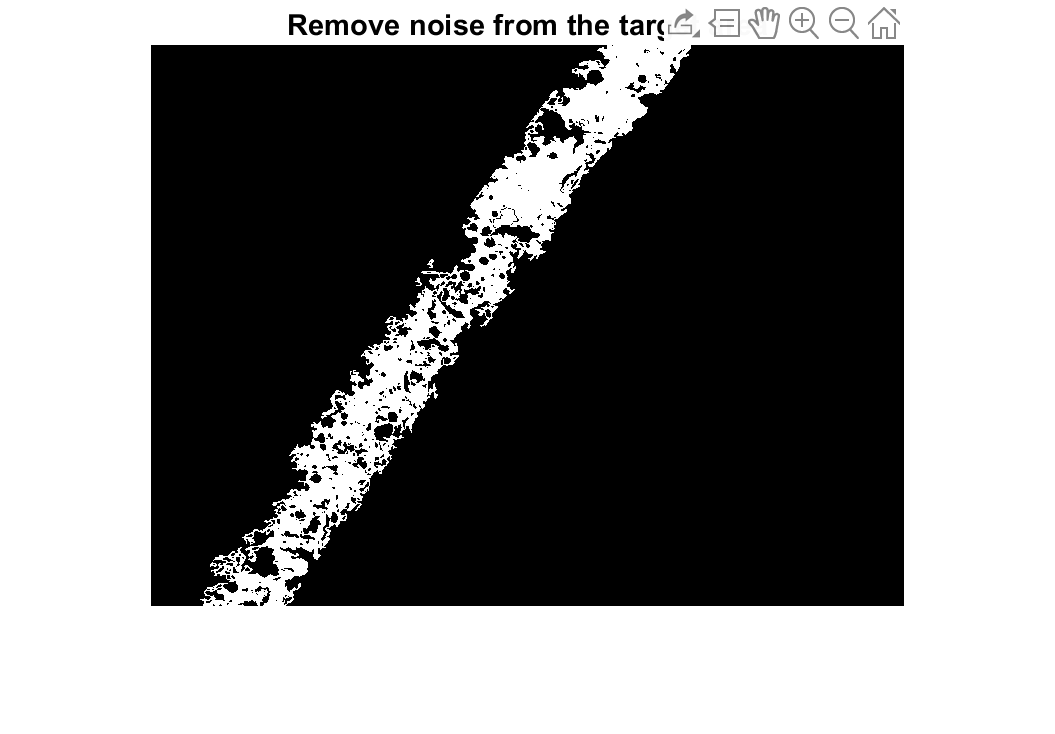

%%%%%%Remove the out-of-target area%%%%%%%%%
boundary_line_1 = @(i) ((y(1)-y(2))/(x(1)-x(2)))*(i-x(1))+y(1);
boundary_line_2 = @(i) ((y(1)-y(2))/(x(1)-x(2)))*(i-x(1)+offset)+y(1);
for i=1:(x(1)-offset)
    for j=1:ori_row
        if j<boundary_line_2(i)
            finalBinImage(j,i)=0;
        end
    end
end
for i=x(2):ori_col
    for j=1:ori_row
        if j>boundary_line_1(i)
            finalBinImage(j,i)=0;
        end
    end
end
%%%%%%Remove the small area of AOI%%%%%%%%%
BW2=bwareaopen(finalBinImage,10);
figure;imshow(BW2);title('Remove noise from the target area');
[y_2,~]=getpts; %边缘追踪起始点

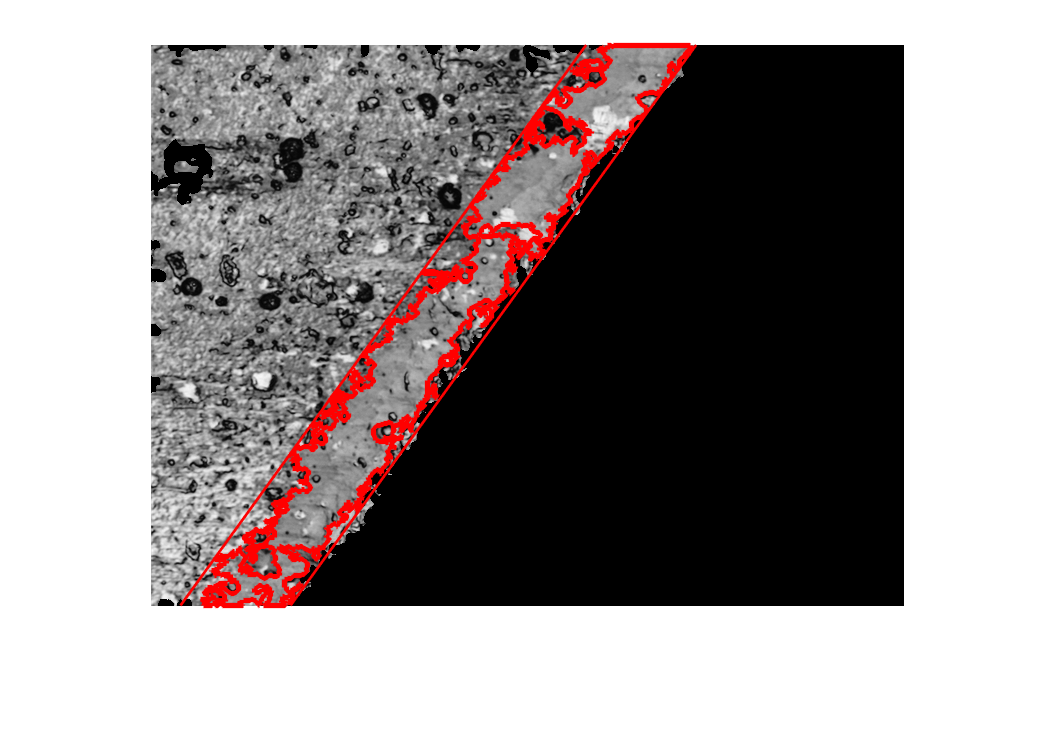

col = round(y_2);
row=find(BW2(:,col),1);
figure;imshow(finalImage);%title('Wear zone boundary');
hold on
contour=bwtraceboundary(BW2,[row col],'W',4);
plot(contour(:,2),contour(:,1),'r','LineWidth',2);
plot(x,y,'r','LineWidth',1);
plot(x-offset,y,'r','LineWidth',1);

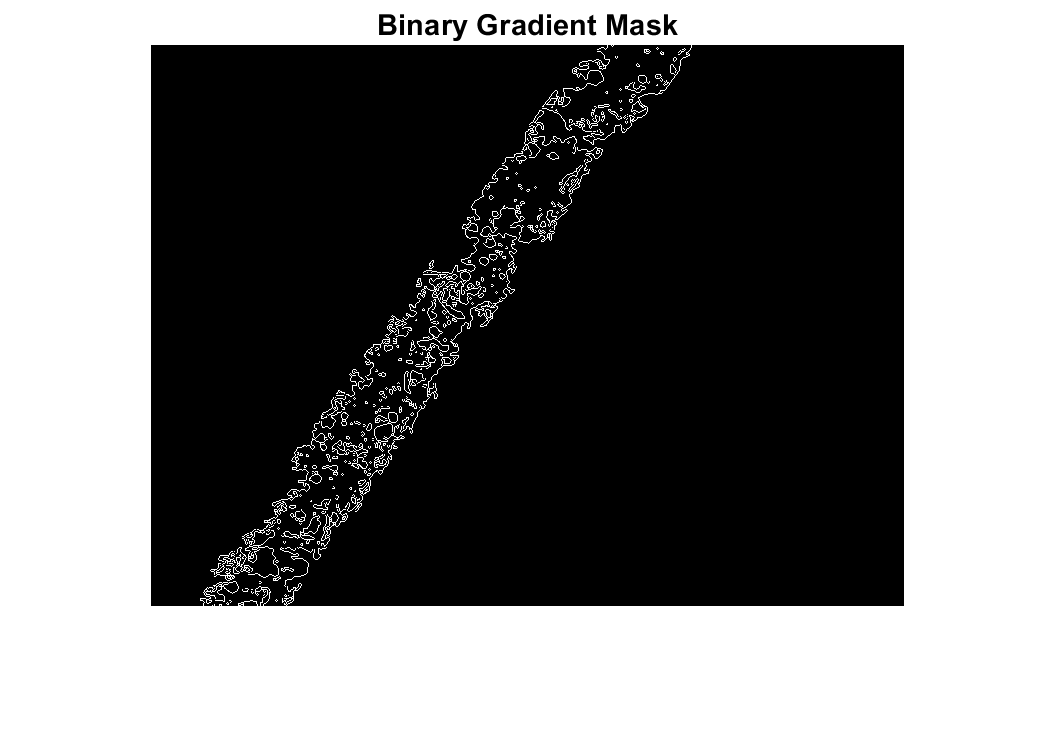

[~,threshold] = edge(BW2,'sobel');
fudgeFactor = 0.5;
BWs = edge(BW2,'sobel',threshold * fudgeFactor);
figure;imshow(BWs);title('Binary Gradient Mask')

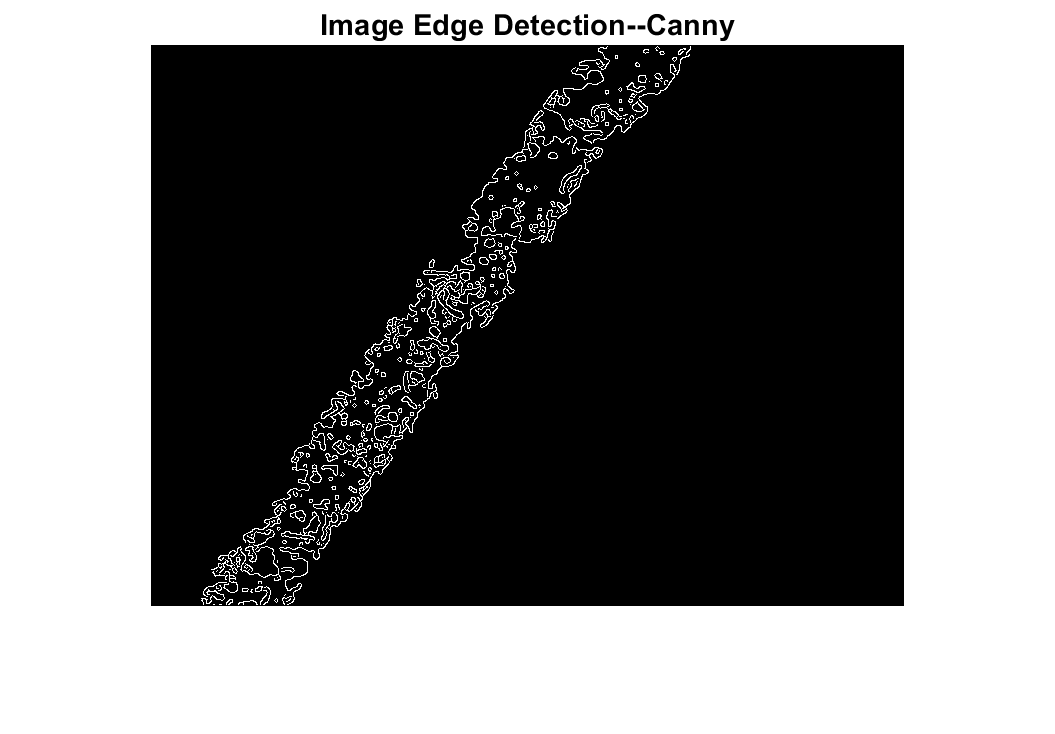

BW3 = edge(BW2,'canny');
figure;imshow(BW3);title('Image Edge Detection--Canny');

% %%%%%%%%%%%%Calculate the area%%%%%%%%%
S = sum(BW2(:));

% %%%%%%%%%八连通链码求周长%%%%%%%%
P1=0;
P2=0;
Nx=0; %记录水平方向连续周长像素点的个数
for i=1:ori_row       %% row index
    for j=1:ori_col   %% column index
        if(BW3(i,j)>0)
            P2=j;
            if((P2-P1)==1)  %判断是否为水平方向连续的周长像素点
                Nx=Nx+1;
            end
            P1=P2;
        end
    end
end

P1=0;
P2=0;
Ny=0; 
for j = 1:ori_col      %% column index
    for i = 1:ori_row       %% row index
        if(BW3(i,j)>0)
            P2=i;
            if((P2-P1)==1)
                Ny=Ny+1; %记录竖直方向连续周长像素点的个数
            end
            P1=P2;
        end
    end
end

SN=sum(sum(BW3));   %计算周长像素点的总数
Nd=SN-Nx-Ny;        %计算奇数码的链码数目
L=sqrt(2)*Nd+Nx+Ny;